# LAB2 MATLAB Programming

李志颖 12210309  夏琮杰12210520

## Introduction

In this lab assignment, we learned about：

1.using matlab to perform convolutional calculations

2.learn something about  Signal Auto-Correlation

3.learn the application : Echo Estimation

## Results and Analysis

## 2.4

### (a)

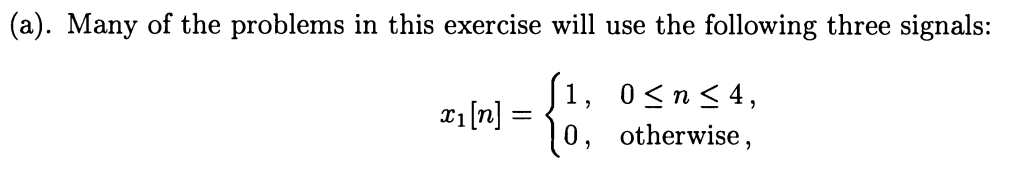

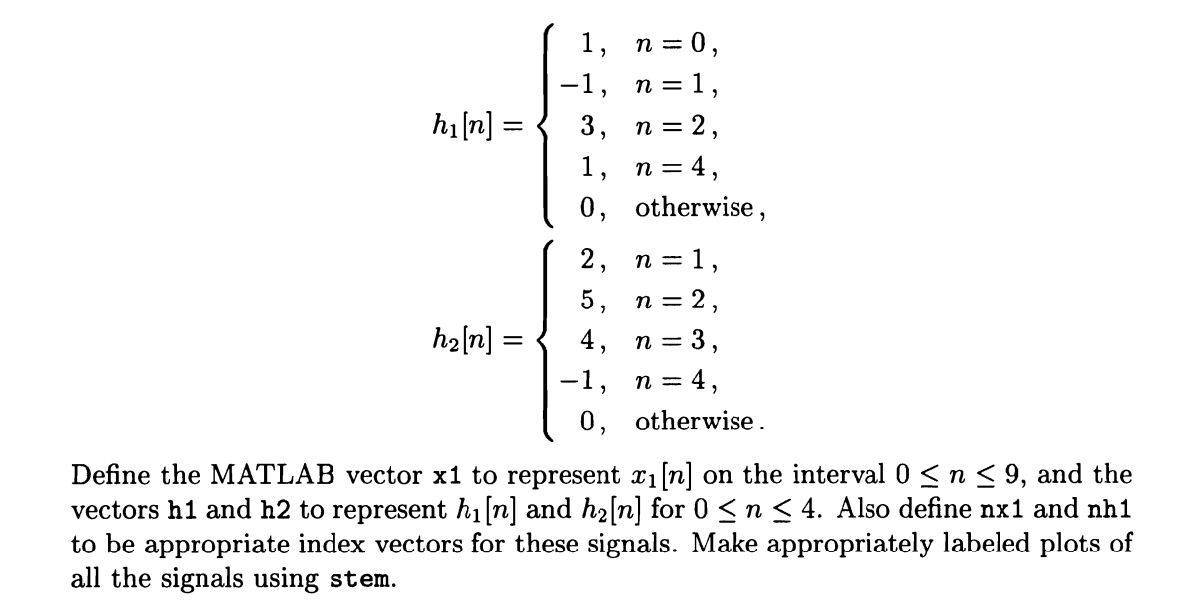

Initialize.

clear; clc; close all;

Define x1,h1,h2, nx1 and nh1. and plot x1 ,h1 and h2

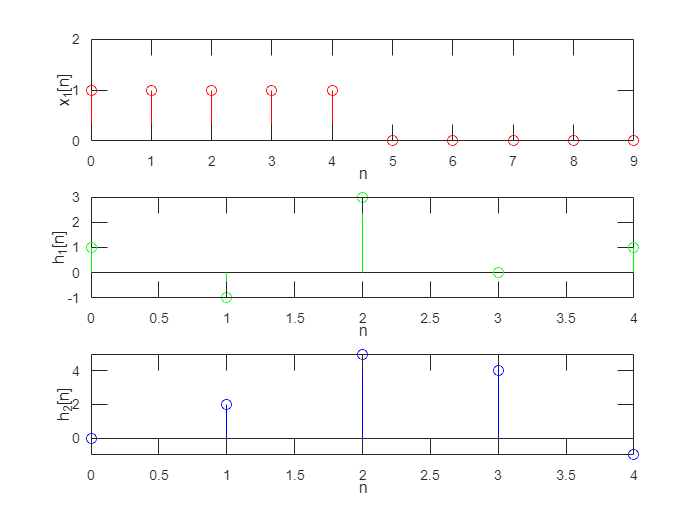

x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;

%plot
subplot(3,1,1);
stem(nx1,x1,'r');
axis([0 9 0 2]);
xlabel('n');ylabel("x_1[n]")

subplot(3,1,2);
stem(nh1,h1,'g');
axis([0 4 -1 3]);
xlabel('n');ylabel("h_1[n]");

subplot(3,1,3);
stem(nh1,h2,'b');
axis([0 4 -1 5]);
xlabel('n');ylabel("h_2[n]");

### (b)

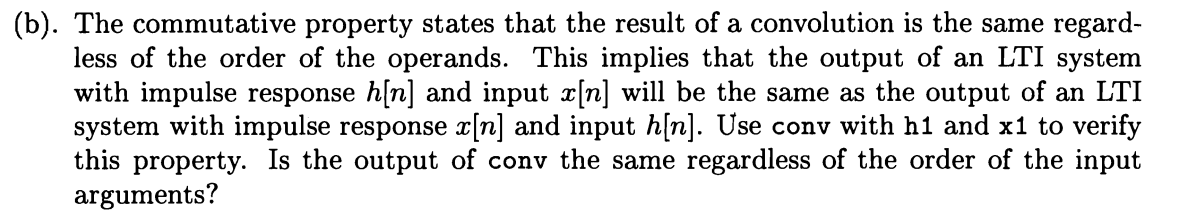

Initialize.

clear; clc; close all;

Calculate x_1 * h_1 ,h_1 *x_1 , and plot them.

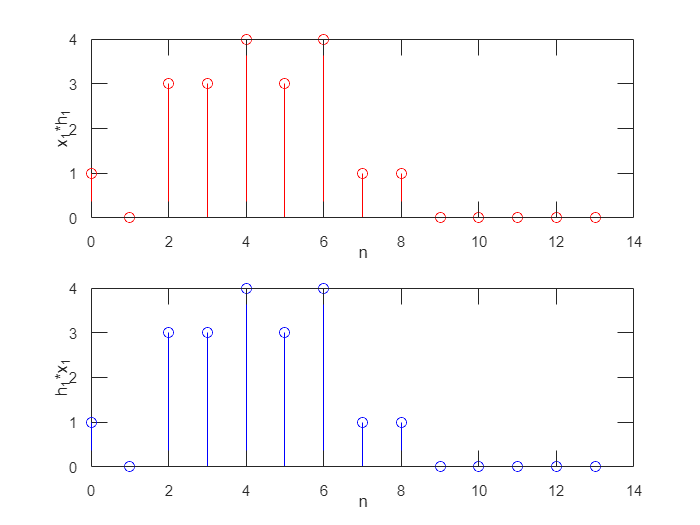

x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
nx1 = 0:9;
nh1 = 0:4;

y1 = conv(x1,h1);
y2 = conv(h1,x1);
ny1 = nx1(1)+nh1(1):nx1(end)+nh1(end);
%plot
subplot(2,1,1);
stem(ny1,y1,'r');
xlabel('n');ylabel('x_1*h_1')

subplot(2,1,2);
stem(ny1,y2,'b');
xlabel('n');ylabel('h_1*x_1');

From the results we konw the answer is yes, the output of conv the same regardless of the input argument.

### (c)

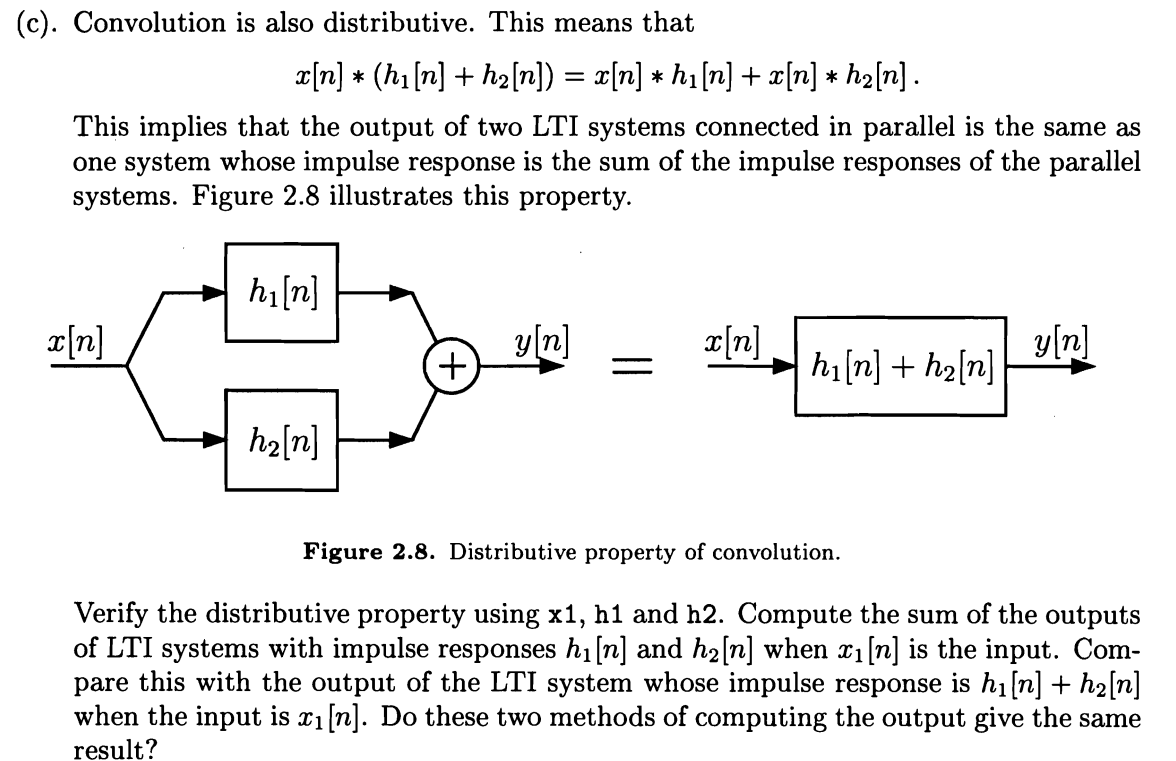

Initialize.

clear; clc; close all;

Calculate and plot

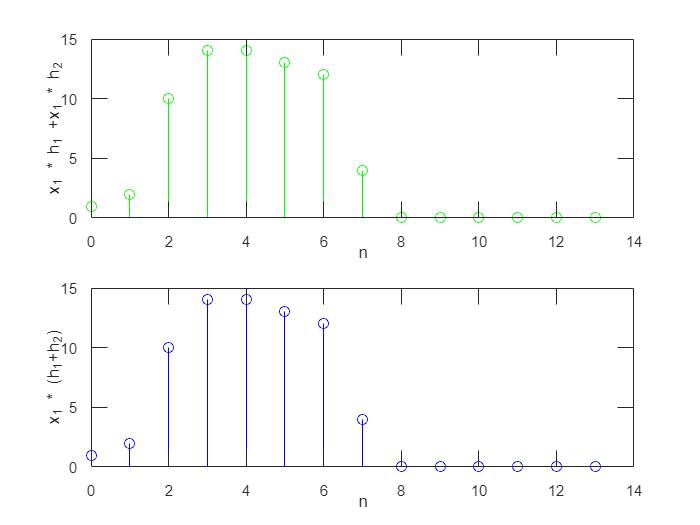

%x1,h1,h2
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;


%x_1 * h_1 +x_1 * h_2
y1 = conv(x1,h1);
y2 = conv(x1,h2);
y_sum = y1+y2;

%x_1 * (h_1+h_2)
h3 = h1 + h2;
y3 = conv(x1,h3);

%plot
ny1 = nx1(1)+nh1(1):nx1(end)+nh1(end);

subplot(2,1,1);
stem(ny1,y_sum,'g');
xlabel('n');ylabel('x_1 * h_1 +x_1 * h_2')

subplot(2,1,2);
stem(ny1,y3,'b');
xlabel('n');ylabel('x_1 * (h_1+h_2)')

From the results we konw these two methods of computing the output give the same result.

### (d)

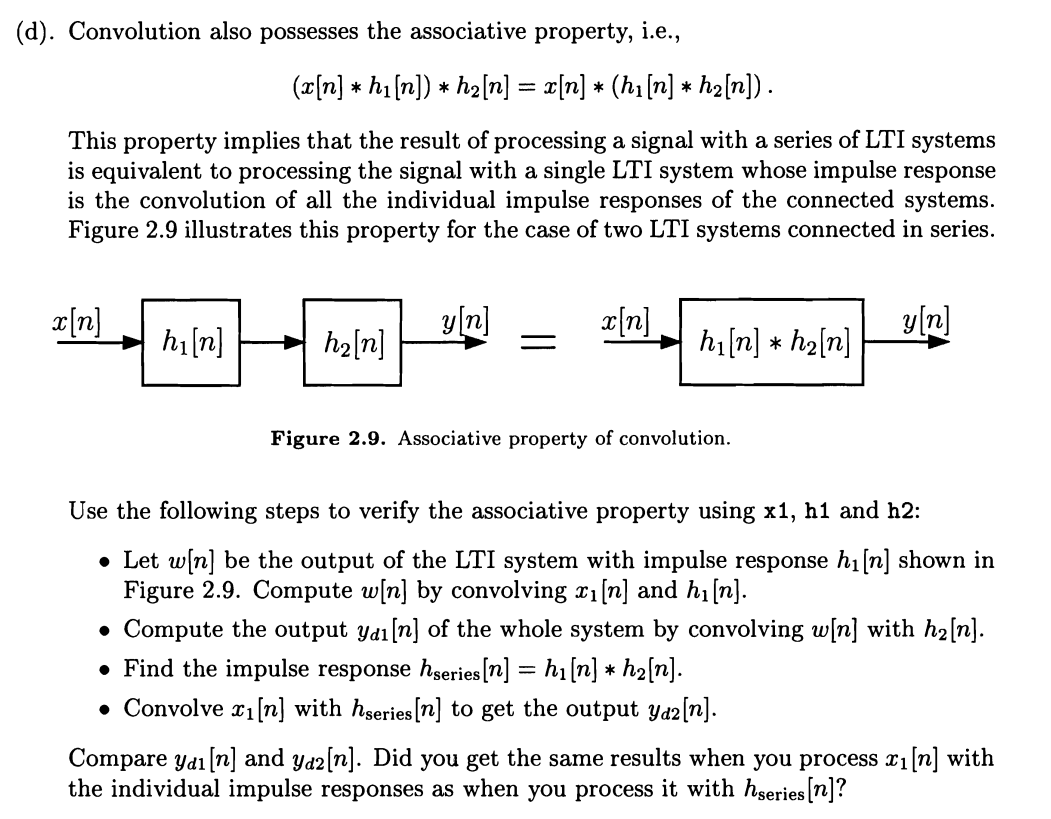

Initialize.

clear; clc; close all;

Calculate and plot

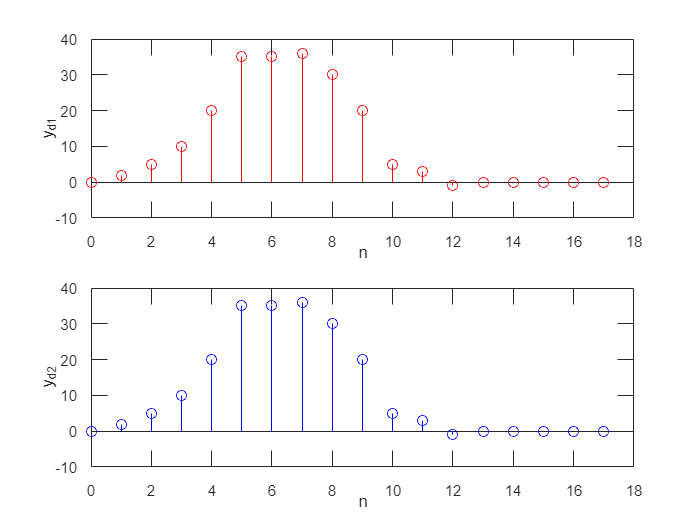

%x1,h1,h2
x1 = [1 1 1 1 1 0 0 0 0 0];
h1 = [1 -1 3 0 1];
h2 = [0 2 5 4 -1];
nx1 = 0:9;
nh1 = 0:4;

% w 
w = conv(x1,h1);
nw = nx1(1)+nh1(1):nx1(end)+nh1(end);

%y_{d1}
yd1 = conv(w,h2);
nyd1 = nw(1)+nh1(1): nw(end)+nh1(end);

% h_s
hs = conv(h1,h2);
nhs = nh1(1)+nh1(1): nh1(end)+nh1(end);

% y_{d2}
yd2 = conv(x1,hs);
nyd2 = nx1(1)+nhs(1): nx1(end)+nhs(end);

%plot
subplot(2,1,1);
stem(nyd1,yd1,'r');
xlabel('n');ylabel('y_{d1}')

subplot(2,1,2);
stem(nyd2,yd2,'b');
xlabel('n');ylabel('y_{d2}')

Yes , I get the same results when I process X_1[n] with the individual impulse responses as then I process it with h_series[n]

## 2.10

### (a)

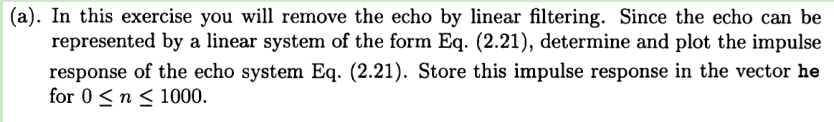

Calculate and plot

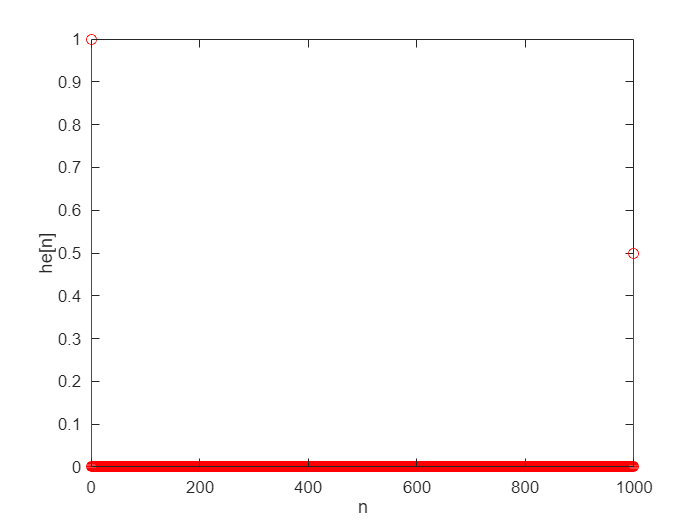

A = 1;
B = [1 zeros(1, 999) 0.5];
ximp = [1 zeros(1, 1000)];
nx = 0:1000;
he = filter(B, A, ximp);

subplot(1, 1, 1);
stem(nx, he, 'r');
axis([0 1000 0 1]);
xlabel('n');
ylabel('he[n]');

### (b)

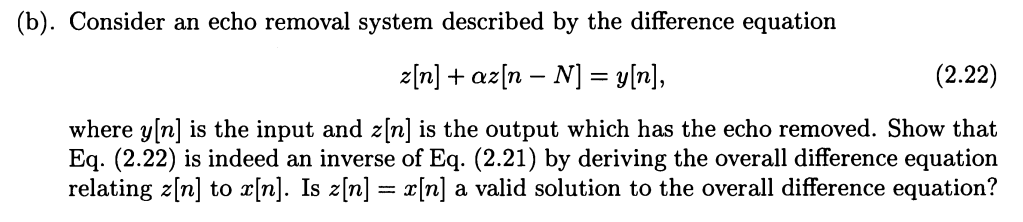

Calculate and plot

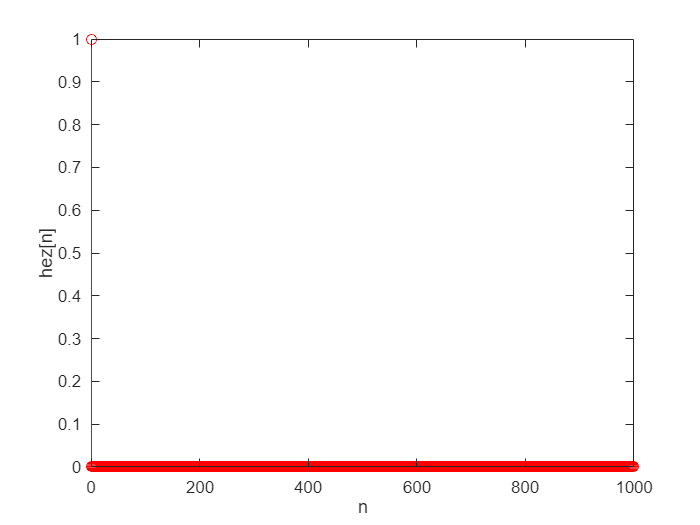

A2 = [1 zeros(1, 999) 0.5];
B2 = [1 zeros(1, 999) 0.5];
ximp = [1 zeros(1, 1000)];
nx = 0:1000;

hz = filter(B2, A2, ximp);

subplot(1, 1, 1);
stem(nx, hz, 'r');
axis([0 1000 0 1]);
xlabel('n');
ylabel('hez[n]');

### (c)

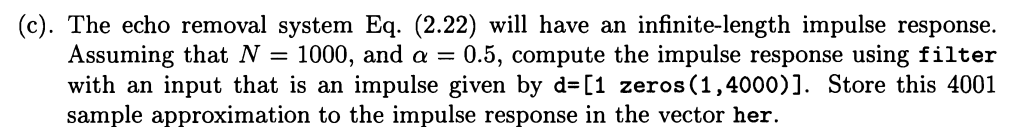

Calculate and plot

A3 = [1 zeros(1, 999) 0.5];
B3 = 1;
d = [1 zeros(1, 4000)];

her = filter(B3, A3, d);

### (d)

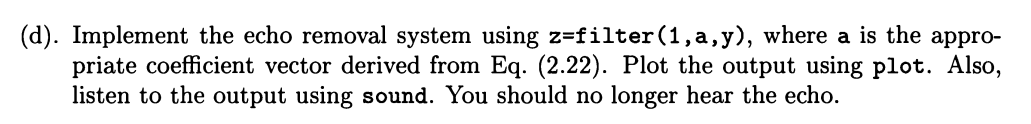

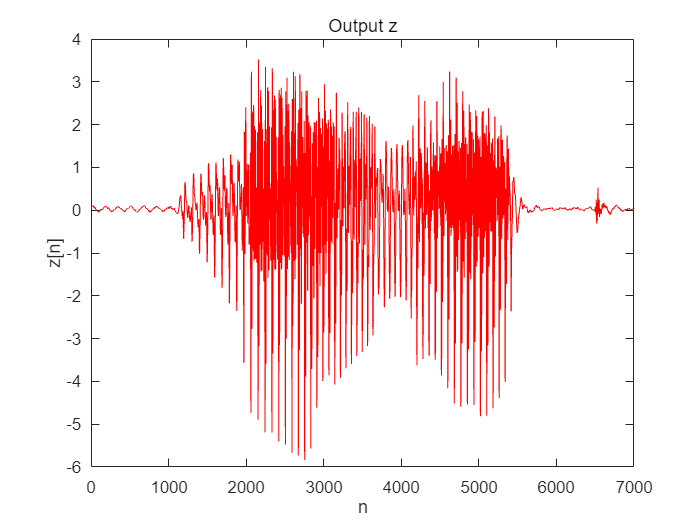

load lineup.mat
sound(y,8192)

a = [1 zeros(1, 999) 0.5];
z = filter(1, a, y);
nz = 1:7000;

plot(nz, z, 'r-');
xlabel('n');
ylabel('z[n]');
title('Output z')

sound(z,8192)

### (e)

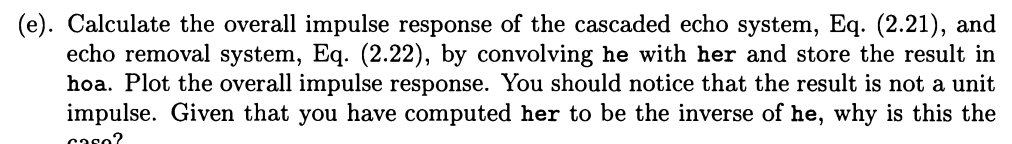

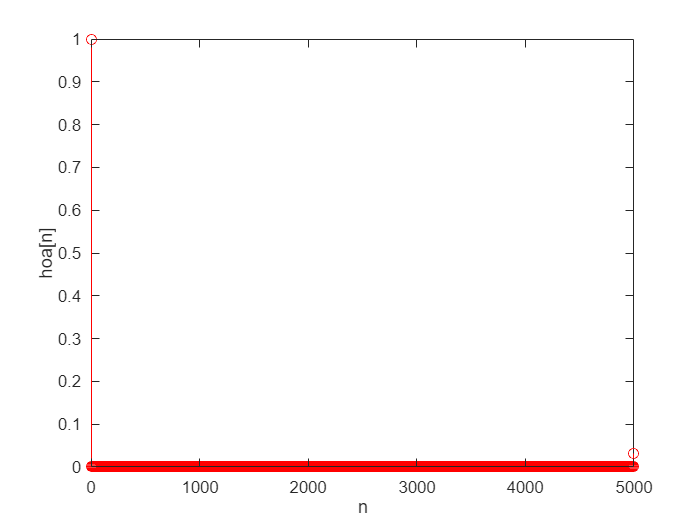

hoa = conv(he, her);
nhoa = 0:5000;

subplot(1, 1, 1);
stem(nhoa, hoa, 'r');
xlabel('n');
ylabel('hoa[n]')

### (f)

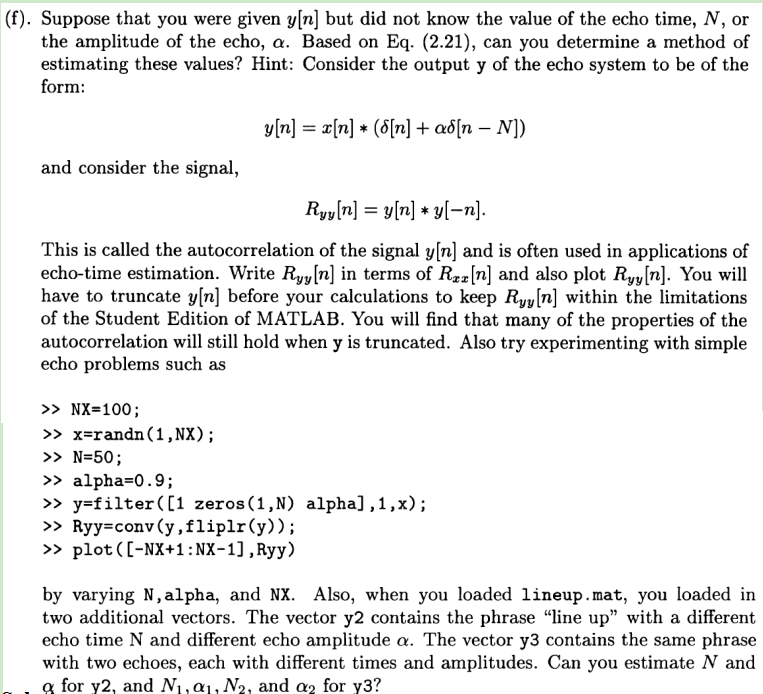

## Experience

1.Search the internet for some useful knowledge

2.Read more of the lab class slides.